Current filtering

filt.wci = 2*pi*20;
filt.di = 1/sqrt(2);
sysHi = tf(filt.wci^2,[1 2*filt.di*filt.wci filt.wci^2]);
sysHi = c2d(sysHi, Ts, 'tustin');
[numHi, denHi] =tfdata(sysHi, 'v');

% filtraggio
proc.iaf = filter(numHi, denHi, out.ia.Data);

## to remove

proc.iatoremove = filter(numHi, denHi, ian);

Setting new quantities wrt motor     TOFIX:current gain

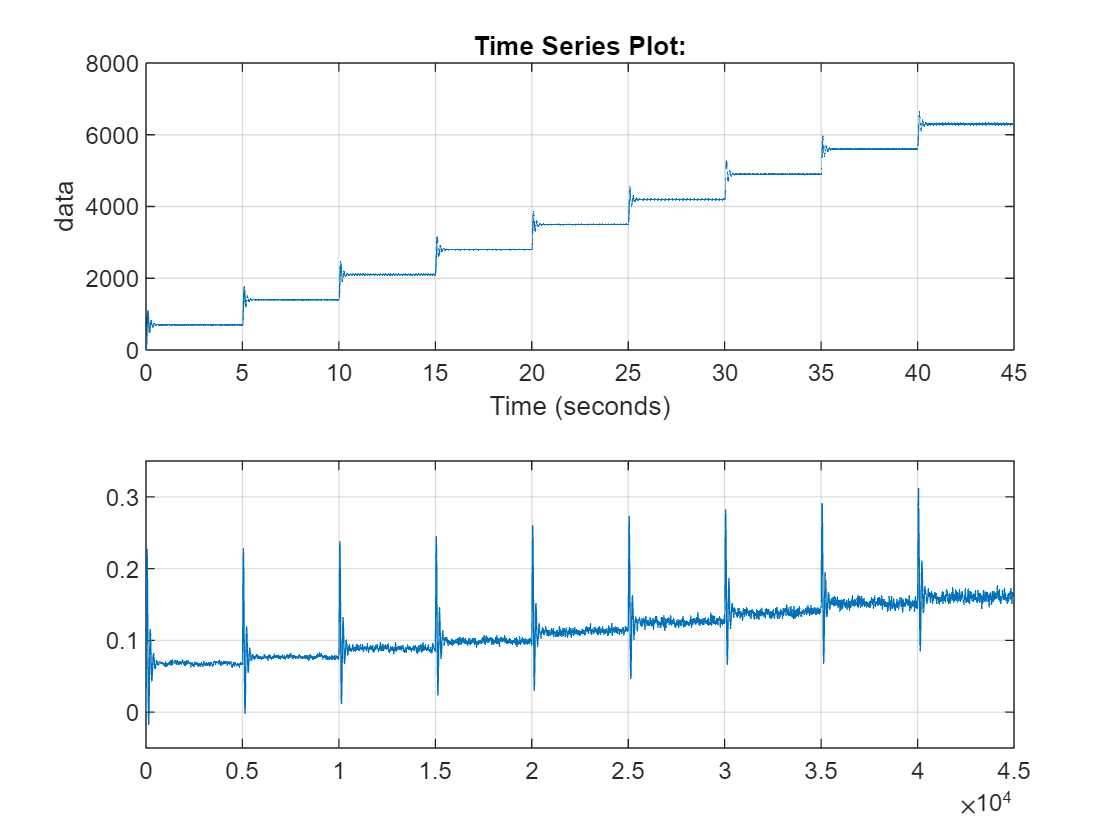

proc.wm = gbox.N*out.wl_meas;
proc.taum = mot.Kt*proc.iaf; 

figure;
subplot(2,1,1);
plot(proc.wm);
grid on;
subplot(2,1,2);
plot(proc.iaf);
grid on;
axis([0 45000 -0.05 0.35])

Least Squares Estimation    

TOFIX:     we tested the function with old data. it is not possible to test the mean due to variable step solver

est.phi=zeros(2,9);
est.Y=zeros(1, 9);
for i=1:9
    temp1 = wmn(5000*(i-1)+200:5000*(i-1)+800);
    temp2 = proc.iatoremove(5000*(i-1)+200:5000*(i-1)+800);
    %temp=proc.wm.Data(5000*(i)+200:5000*(i)+800);
    est.phi(1,i)=mean(temp1);
    est.phi(2,i)=1/gbox.N*sign(est.phi(1,i));
    est.Y(i)=mean(temp2); 
end

est.theta=((est.phi*est.phi.')^-1)*est.phi*est.Y.'

est = struct with fields:
      phi: [2×9 double]
        Y: [-0.0015 -0.1068 -0.1046 -0.1085 -0.1187 -0.1278 -0.1333 -0.1501 -0.1525]
    theta: [2×1 double]


PAY ATTENTION: save est.theta for each simulation